#     Ecuaciones lineales de primer orden  

# Problemas de valor inicial

## Adaptive and  Multistep methods 

## Stiff systems and Implicit methods

### Epidemia

The following ODEs have been proposed as a model of an epidemic:


$$\frac{\mathrm{d}}{\mathrm{d}t}S=-a\;S\;I$$



$$\frac{\mathrm{d}}{\mathrm{d}t}I=a\;S\;I-r\;I$$



$$\frac{\mathrm{d}}{\mathrm{d}t}R=r\;I$$


where S = the susceptible individuals, I = the infected, R = the recovered, a = the infection rate, and r = the recovery rate. A city has 10,000 people, all of whom are susceptible. If a single infectious individual enters the city at t = 0, compute the progression of the epidemic until the number of infected individuals falls below 10. Use the following parameters: a = 0.002/(person · week) and r = 0.15/d.

Develop time-series plots of all the state variables.

Suppose that after recovery, there is a loss of immunity that causes recovered individuals to become susceptible.

This reinfection mechanism can be computed as ρR, where ρ = the reinfection rate. Modify the model to include this mechanism and repeat the computations using ρ = 0.03/d.

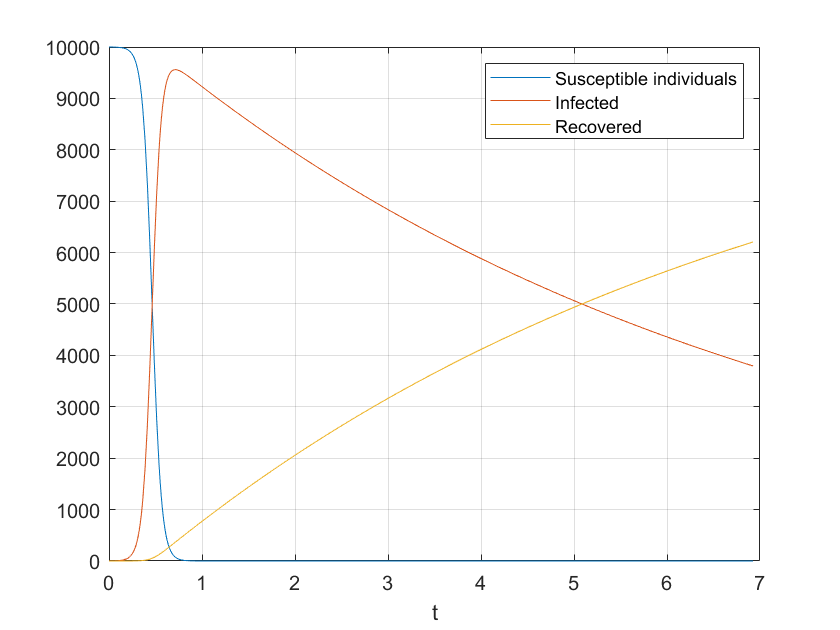

%
a=0.002;
r=0.15;
t0=0;
f=@(t,y) [-a*y(1)*y(2); a*y(1)*y(2)-r*y(2); r*y(2)];
tf=10;
h=0.1;
relTol = 1e-5;
max = 400;
y0=[10000;1;0];
[t,y] = rkf45(f, y0, t0, tf, h, relTol, max);

plot(t,y(1,:));
xlabel('t');
hold on;
grid on;
plot(t,y(2,:));
xlabel('t');
plot(t,y(3,:));
xlabel('t');
legend('Susceptible individuals','Infected','Recovered');
hold off;

### Variable step size

Solve the following ODE from t=0 to 4, where y(0)=0.5. Obtain the solution for a relative tolerance of ${10}^{-5}$:


$$\frac{\mathrm{d}}{\mathrm{d}t}y=10e^{-\left({\left(t-2\right)}^2 /2{\left(0\ldotp 075\right)}^2 \right)} -0\ldotp 6y$$


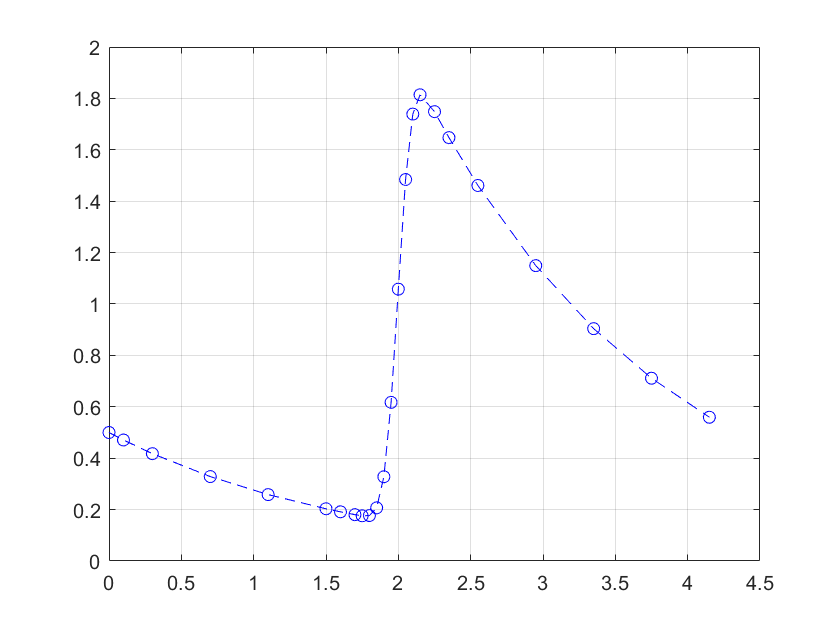

% Ejemplo 21.2 Chapra (3ed)
ydot =  @(t,y) 10*exp(-(t-2)^2/(2*0.075^2))-0.6*y;
y0 = 0.5;
h = 0.1;
relTol = 1e-5;
max = 400;
[t,y] = rkf45(ydot, y0, 0, 4, h, relTol, max);
       
plot(t,y,'b--o');
grid on;

Solve the initial value problem within a relative tolerance of ${10}^{-6}$:

$y^{\prime } =t\;y+t^3$         $y\left(0\right)=1$          t in [0,1]

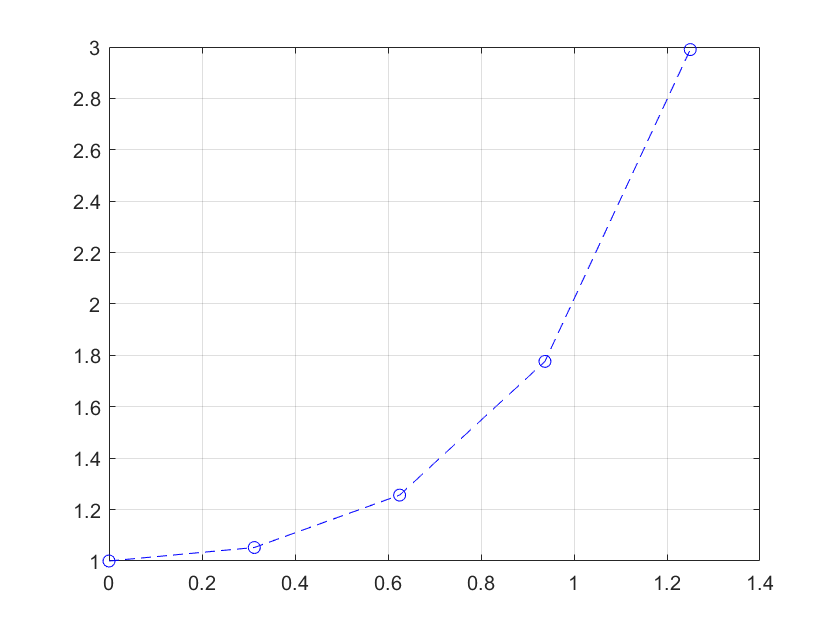

ydot =  @(t,y) t*y+t^3;
y0 = 1;
t0=0;
tf=1;
h = 10;
relTol = 10E-6;
max = 400;
[t,y] = rkf45(ydot, y0, t0, tf, h, relTol, max);
       
plot(t,y,'b--o');
grid on;

### Mutistep 

Solve the initial value problem:

$y^{\prime } =\frac{1}{2}\left(1+x\right)y^2$         $y\;\left(0\right)=1$          t in [0,1]

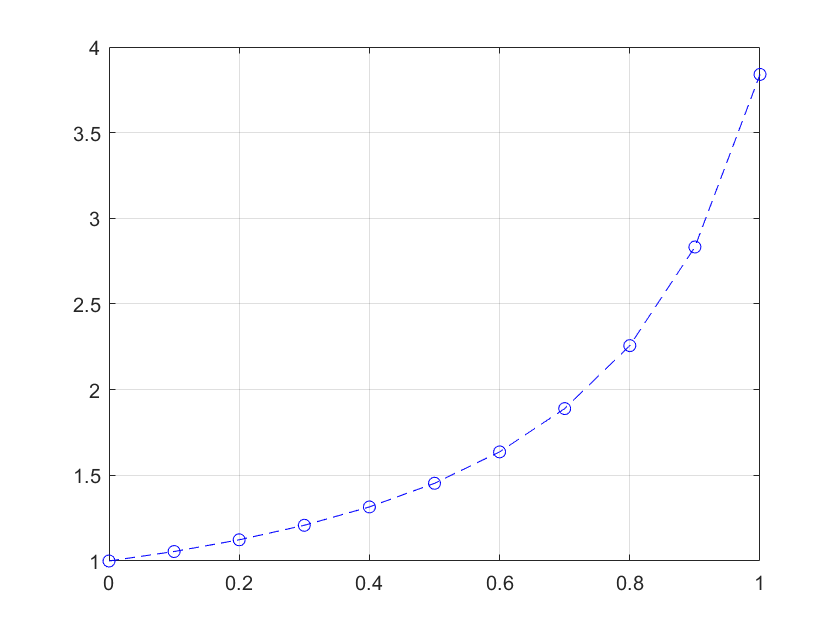

ydot =  @(t,y) 1/2 * (1+t)*y^2;
y0 = 1;
t0=0;
tf=1;
h = 0.1;
[t,y]=odeABM4(ydot,y0,t0,tf,h);
plot(t,y,'b--o');
grid on;

Solve the initial value problem:

$y^{\prime } =\frac{-2y}{1+t}$         $y\;\left(0\right)=2$          t in [0,2.5]

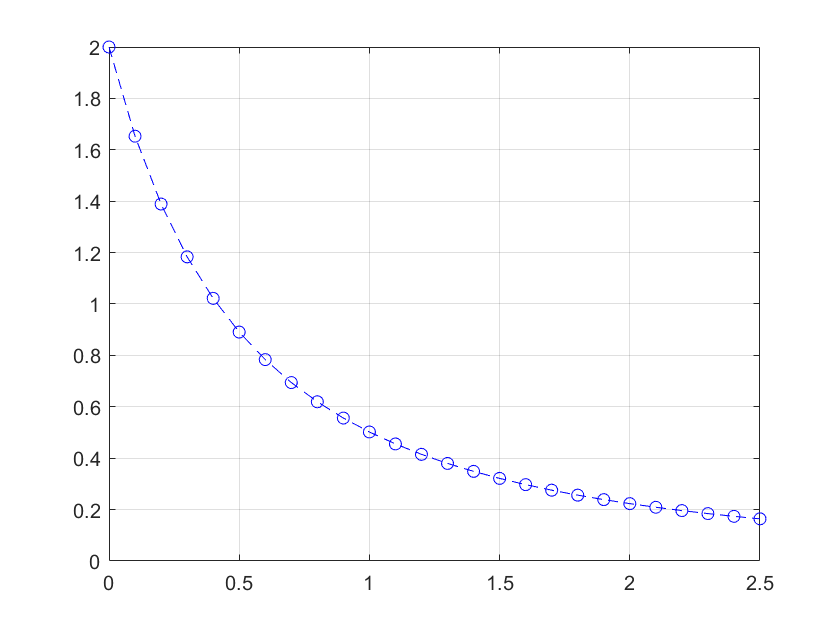

ydot =  @(t,y) -2*y/(1+t);
y0 = 2;
t0=0;
tf=2.5;
h = 0.1;
[t,y]=odeABM4(ydot,y0,t0,tf,h);
plot(t,y,'b--o');
grid on;

### Stiff equations

A problem is stiff if the solution being sought varies slowly, but there are nearby solutions that vary rapidly, so the numerical method must take small steps to obtain satisfactory results.

Apply the Euler and Backward Euler methods to the initial value problem

$y^{\prime } =y+8y^2 -9y^3$         $y\;\left(0\right)=0\ldotp 5$          t in [0,3]

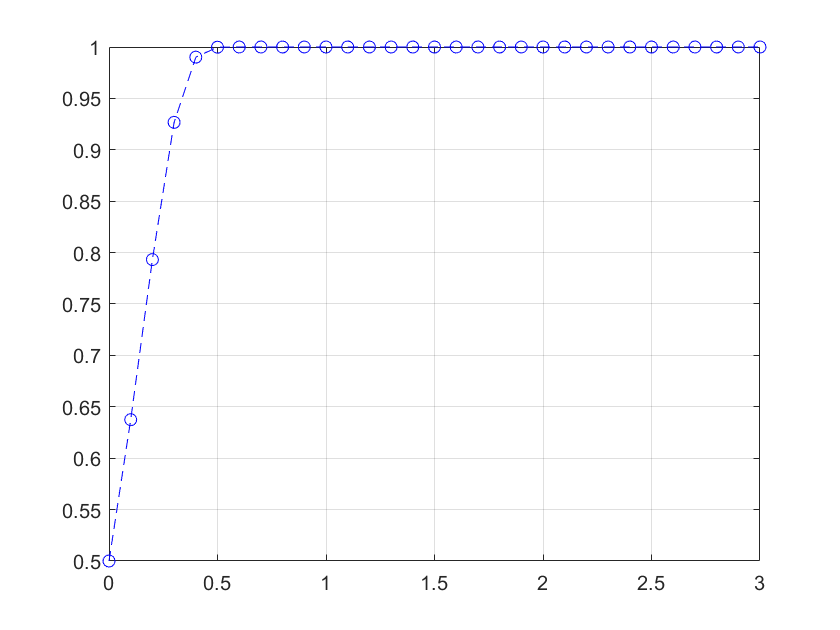

ydot =  @(t,y) y+8*y^2-9*y^3;
y0 = 0.5;
t0=0;
tf=3;
h = 0.1;
[t,y]=ivpsV(ydot,y0,t0,tf,h,'euler');
plot(t,y,'b--o');
grid on;

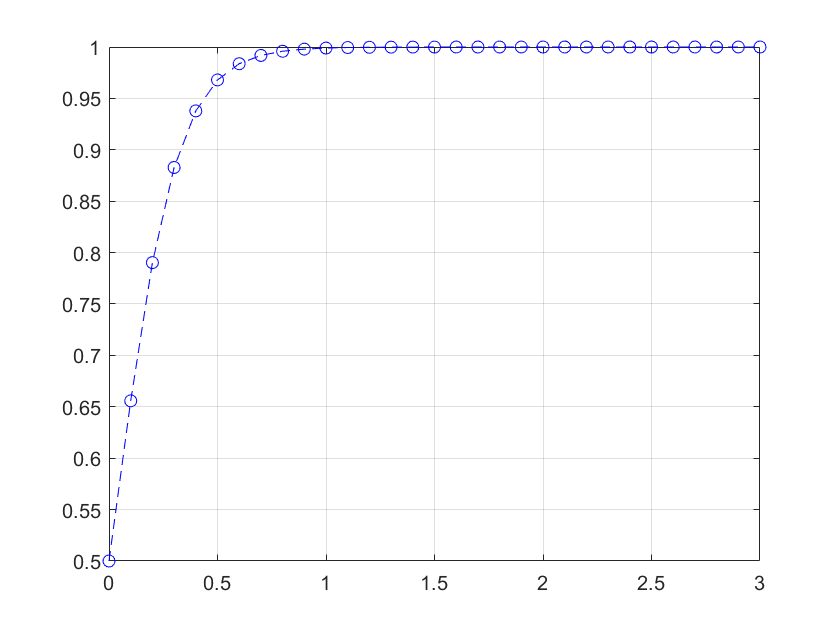

[t,y]=ImplicitEuler(ydot,y0,t0,tf,h);
plot(t,y,'b--o');
grid on;

function [t,y] = rkf45(f,y0,t0,tf,h,relTol,max)
    t(1) = t0;
    y(:,1) = y0;
    tk = 0;
    
    i = 1;
    cond = true;
    while cond
        wi = y(:,i);
        ti = t(i);
        s1 = f(ti,wi);
        s2 = f(ti+(h/4),wi+(h/4*s1));
        s3 = f(ti+(3/8)*h,wi+(3/32)*h*s1+(9/32)*h*s2);
        s4 = f(ti+(12/13)*h,wi+(1931/2197)*h*s1 - (7200/2197)*h*s2 + (7296/2197)*h*s3);
        s5 = f(ti+h,wi+(439/216)*h*s1-8*h*s2+(3680/513)*h*s3-(845/4104)*h*s4);
        s6 = f(ti+h/2,wi-(8/27)*h*s1+2*h*s2 - (3544/2565)*h*s3 + (1859/4104)*h*s4 - (11/40)*h*s5);
        win = wi + h*((25/216)*s1+(1408/2565)*s3+(2197/4104)*s4-(1/5)*s5);
        zin = wi + h*((16/135)*s1 + (6656/12825)*s3 + (28561/56430)*s4 - (9/50)*s5 + (2/55)*s6);
     
        if norm((zin-win)./zin)>relTol
            h = h/2;
        else
            y(:,i+1) = zin;
            t(i+1) = ti+h;
            tk = t(i+1);
            h = h*2;
            i = i+1;
        end
        
        cond = tk<tf && i<max;
        
    end
end

function [t,y] = odeABM4(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    
    t4 = t(4);
    [~,y(:,1:4)] = ivpsV(f,y0,t0,t4,h,'rk4');
    
    fm4 = f(t(1),y(1));
    fm3 = f(t(2),y(2));
    fm2 = f(t(3),y(3));
    fm1 = f(t(4),y(4));
    
    for i=4:n-1
        y(i+1) = y(i) + h*((55/24)*fm1 - (59/24)*fm2 + (37/24)*fm3 - 9/24*fm4);
        fm4 = fm3;
        fm3 = fm2;
        fm2 = fm1;
        fm1 = f(t(i+1),y(i+1));
    end
    
end

function [x,y] = ivpsV( f, y0, x0, xf, h, method)
    x= x0:h:xf;
    n=length(x);
    m = length(y0);
    y=zeros(m,n);
    y(:,1)=y0;
    
    for i=1:1:n-1
        switch method
        case 'euler'
            phi=f(x(i),y(:,i));
            y(:,i+1)=y(:,i)+phi*h;
        case 'midpoint'
            ymid=y(i)+f(x(i),y(:,i))*h/2;
            phi=f(x(i)+h/2,ymid);
            y(:,i+1)=y(:,i)+phi*h;
        case 'heun'
            s1=f(x(i),y(:,i));
            predictor=y(:,i)+s1*h;
            s2= f(x(i+1), predictor);
            phi = (s1+s2)/2;
            y(:,i+1)=y(:,i)+phi*h;
        case 'rk4'
            k1=f(x(i),y(:,i));
            k2=f(x(i)+h/2,y(:,i)+k1*h/2);
            k3=f(x(i)+h/2,y(:,i)+k2*h/2);
            k4=f(x(i)+h, y(:,i)+k3*h);
            y(:,i+1)=y(:,i)+(k1+2*k2+2*k3+k4)*h/6;
        end
    end
end

function [t,y] = ImplicitEuler(f,y0,t0,tf,h)
    t = t0:h:tf;
    n = length(t);
    m = length(y0);
    y = zeros(m,n);
    y(:,1) = y0;
    
    for i=1:n-1
      k = @(yn) yn - y(:,i) - f(t(i+1),yn)*h;  
      [yi,~] = newRap(k,y(:,i));
      y(:,i+1) = yi;
    end
    
end

function [x,i]=newRap(f,xi)
    fsym=sym(f);
    dfs=diff(fsym);
    df=matlabFunction(dfs);
    xp=xi;
    i=0;
    x=xp-f(xp)/df(xp);
    MAX=1000;
    if dfs==0 && f(x)~=0, error('La derivada de la función es 0, raíces son imaginarias'), end
    while abs((x-xp)/x)>eps && f(x)~=0 && i<MAX
        xp=x;
        x=xp-f(xp)/df(xp);
        i=i+1;
    end
end